## VSC-HVDC Admittance Scan and Stability Analysis 

This project shows how to detect instabilities in a voltage-source converter high-voltage direct current (VSC-HVDC) system using an impedance scanning technique.

The HVDC system has two converter stations connected by DC transmission lines that enable power transfer between the two remote locations.

This project demonstrates how to:

- Perform admittance scanning (D, Q, DC) for a two-terminal VSC-HVDC system.

- Construct the full multivariable admittance matrix.

- Use the generalized Nyquist Criterion (GNC) to evaluate system stability.

- This frequency-domain stability analysis incorporates both AC- and DC-side dynamics to identify potential resonances and control interactions that may compromise system performance. To validate the frequency-domain stability assessment, you perform a time-domain simulation under a small disturbance scenario and compare the results.

### **System Description**

This figure shows the unit test model which contains an offshore wind farm connected to the onshore AC grid through a $\pm \;400\;\textrm{kV}$ VSC-HVDC network. 

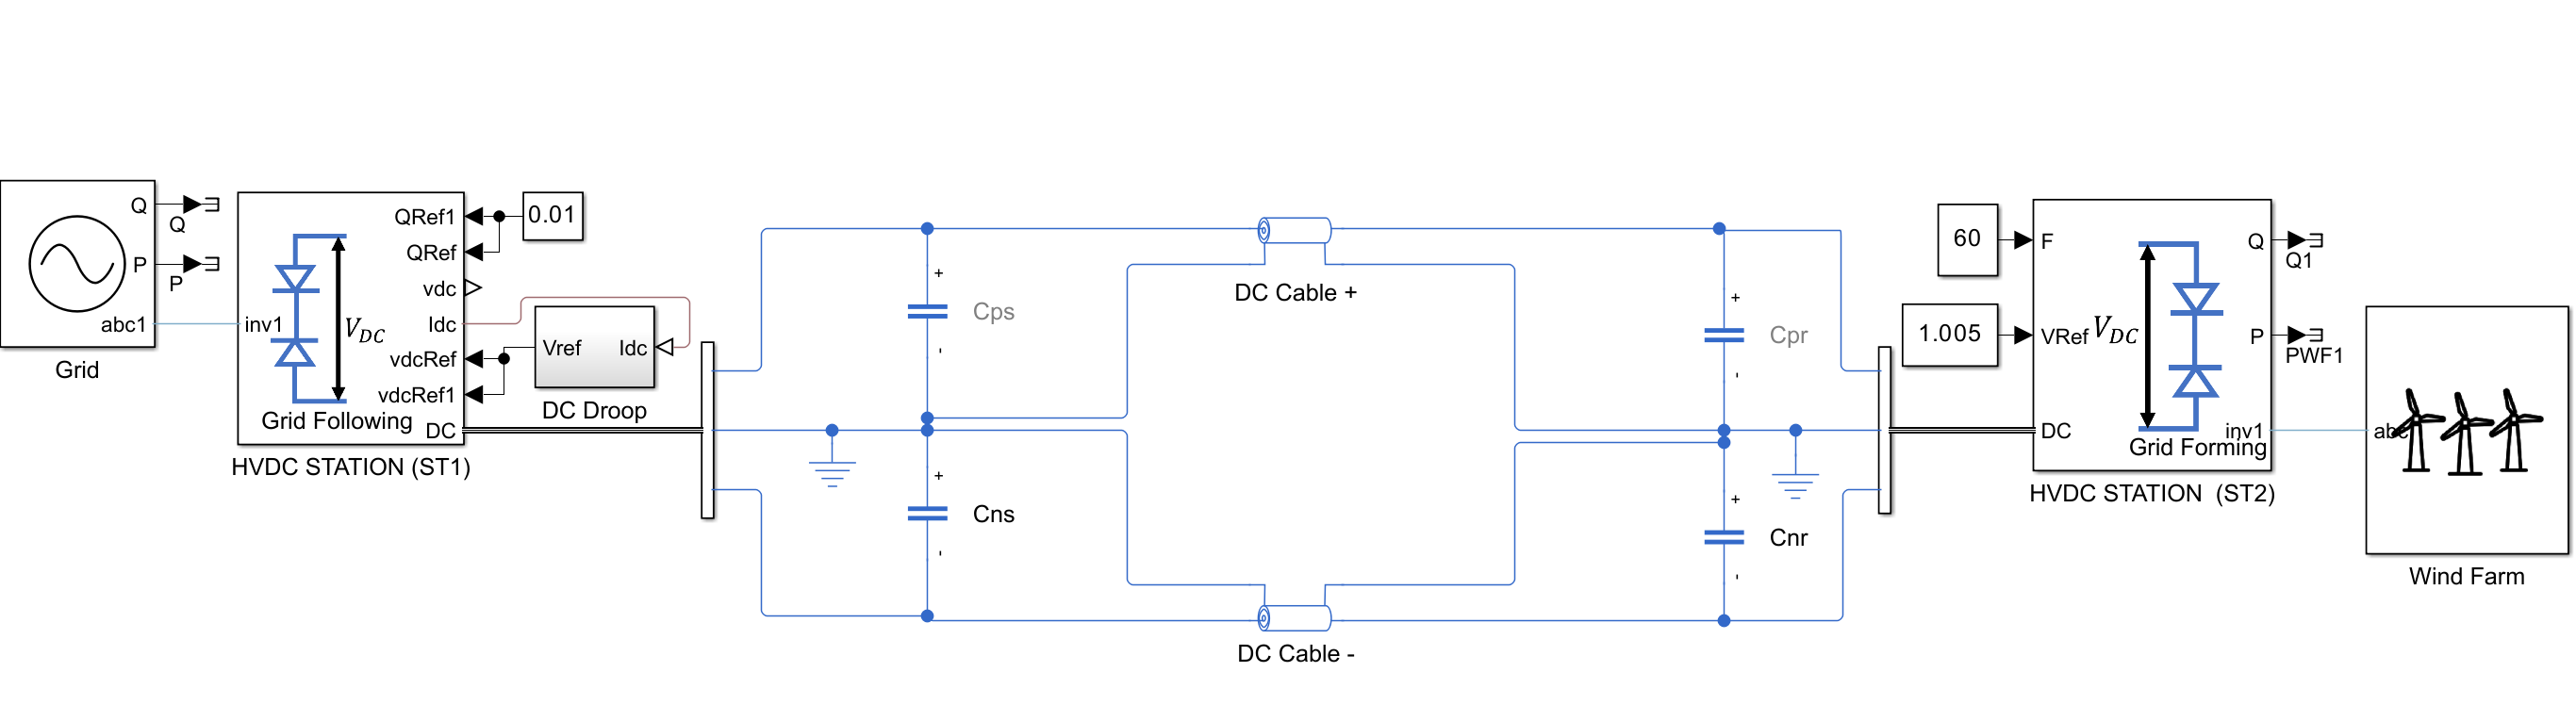

- The VSC-HVDC network consists of onshore and offshore HVDC stations connected through 125 km long bipolar HVDC cables. 

- The wind turbines connect to the offshore wind farm using fully-rated back-to-back converters.

- The wind farm has an installed capacity of 160 MW, where each wind turbine can generate a rated power of 18 MW at a wind speed of 11 m/s.

- The offshore converter is grid-forming, while the onshore VSC is grid-following with DC-voltage control and PLL-based synchronization.

### Admittance Scan Tool

This tool determines the frequency vs admittance characteristics of the grid-connected system using only measurements from the point of interconnection (POI). 

These admittance characteristics are valid for the operating condition over which you estimate the admittance. This tool estimates the admittance in the D-Q frame. 

This system of equations defines the relationship between the admittance of an Inverter-based resource (IBR), $Y$, perturbed voltages at POI, $\Delta V$, and the perturbed currents, $\Delta i$, along the D and Q axis are given below.

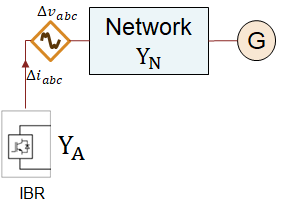


$$\left\lbrack \begin{array}{cc}
Y_{\textrm{dd}}  & Y_{\textrm{dq}} \\
Y_{\textrm{qd}}  & Y_{\textrm{qq}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta V}_d \\
{\Delta V}_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\Delta i}_d \\
{\Delta i}_q 
\end{array}\right\rbrack$$


## Admittance Scan of VSC-HVDC based Offshore Wind Farm

This figure shows how the admittance scan is performed for the HVDC network with the AC-side scan block and DC-side scan block.

The AC admittance scan block has a phase-locked loop (PLL) that tracks the steady-state grid frequency and converts the measured voltages and currents into their respective D and Q components. 

The block captures the measured voltages and currents from the AC side and DC side. 

Similarly, the DC admittance scan block injects a pseudorandom binary sequence (PRBS) voltage disturbance on the DC side and captures the measured voltages and currents from the AC and DC sides. 

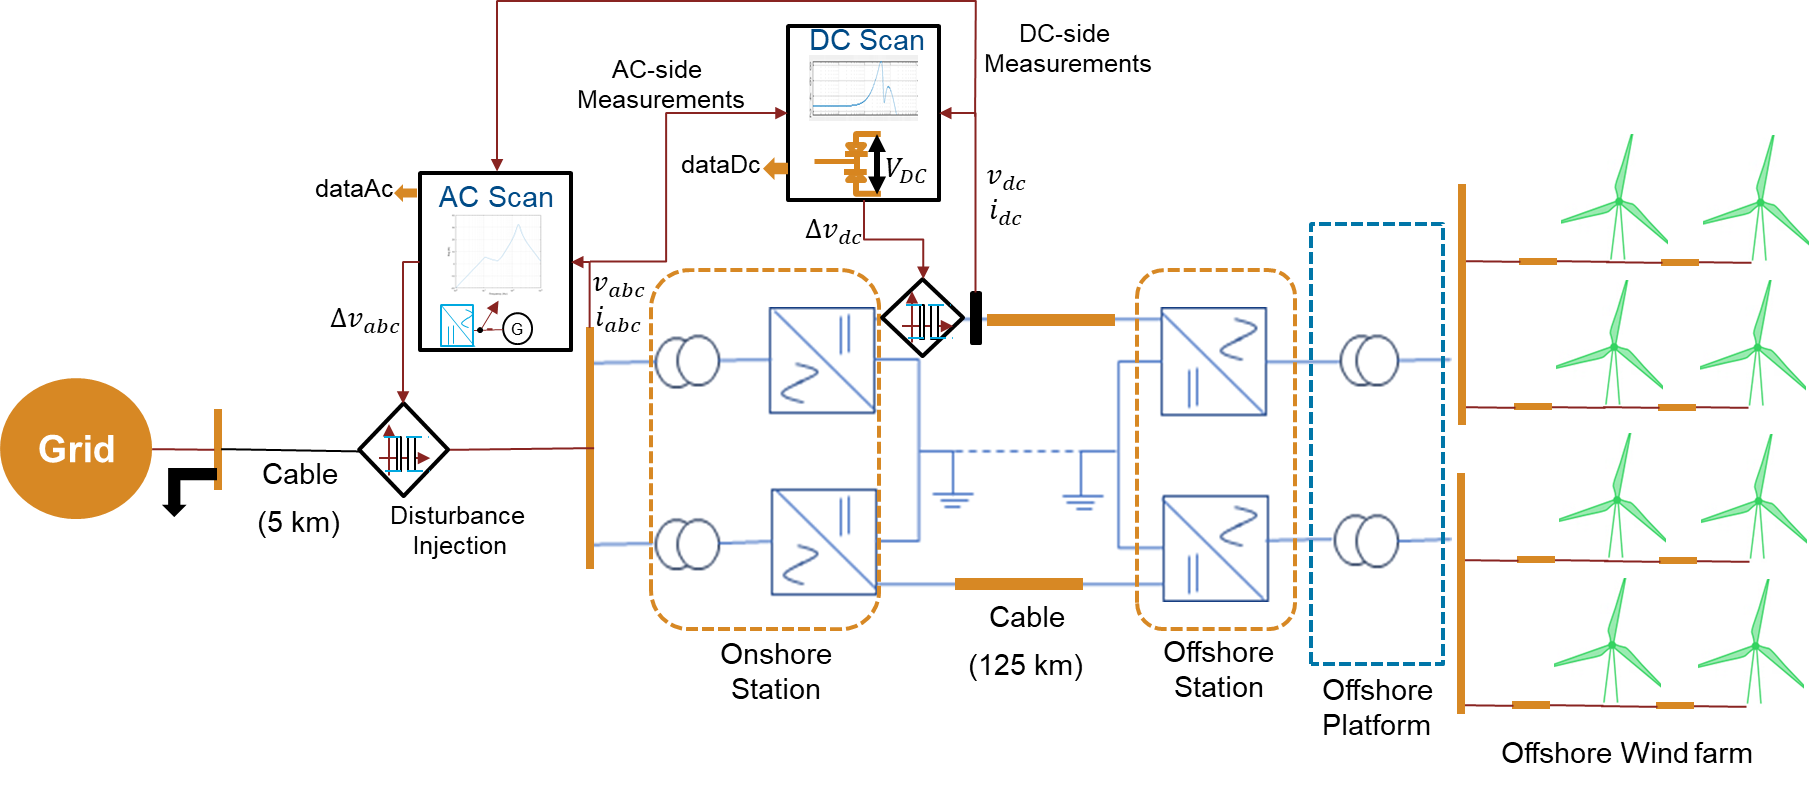

#### **Benefits of Scan Including DC-Side Dynamics** 

- Using only DQ admittance modeling ignores the effects of the AC network on the DC terminals and vice-versa. 

- The interactions between the AC and DC sides can introduce additional dynamics and potential instability, particularly if there are resonances or adverse interactions that are not accounted for in the system design. 

This work performs stability assessment by performing admittance scan on both AC and DC sides of the HVDC stations.

Considering the interaction between the DC-side and AC-side dynamics, the  relationship among the admittance, perturbed voltages, and currents along the D- and Q-axis are given below.


$$\left\lbrack \begin{array}{ccc}
Y_{\textrm{dd}}  & Y_{\textrm{dq}}  & Y_{\textrm{dDc}} \\
Y_{\textrm{qd}}  & Y_{\textrm{qq}}  & Y_{\textrm{qDc}} \\
Y_{\textrm{Dcd}}  & Y_{\textrm{Dcq}}  & Y_{\textrm{Dc}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta V}_d \\
{\Delta V}_q \\
{\Delta V}_{\textrm{dc}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\Delta i}_d \\
{\Delta i}_q \\
{\Delta i}_{\textrm{dc}} 
\end{array}\right\rbrack$$


## **Steps for Scanning**

The goal is to extract frequency-domain small-signal models (admittance) of each converter station in the VSC-HVDC system under normal operating conditions. 

You can use these admittance models to analyze control interactions and assess stability.

This figure shows how to perform stability assessment for the HVDC system, using admittance scan.

                         **STEP 1**                                               **STEP 2**                                                    **STEP 3**

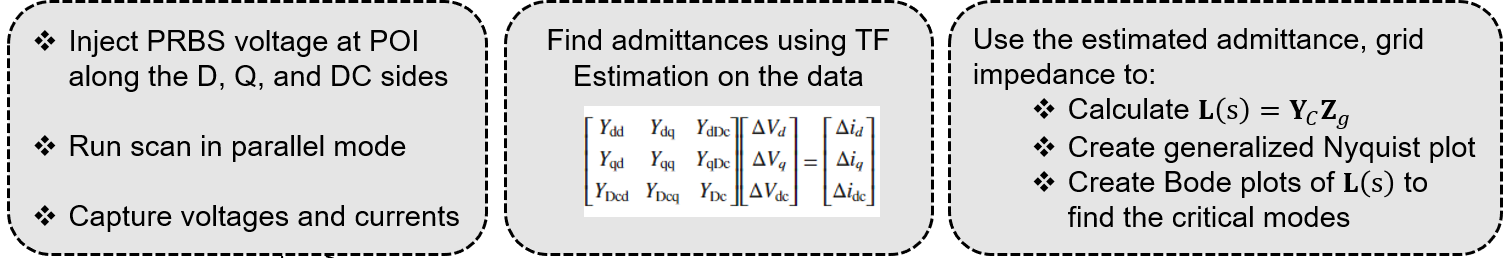

### **Step 1: Inject Disturbance and Capture Voltage and Current Signals**

- First, scan on the AC side of the network by injecting a PRBS voltage disturbance along the D- and Q-axis using the AC Scan block.

- You measure the perturbed voltages and currents from the AC and DC buses using the AC Scan block and store the measured voltages and currents in the workspace variable, `dataAC`. 

- Similarly, you perform the scanning on the DC side by injecting a voltage disturbance on the DC bus and measure the perturbed voltages and currents from the AC and DC buses using the DC Scan block, and store them as workspace variable, `dataDc`.

mdl = "HVDCScan"; % HVDC model
open_system(mdl); % Load the model
% Scan block parameters
scan.f=(1:1:3e3); % Range of disturbance frequency (Hz)
scan.samplingfrequency = 2e4; % Sampling frequency for scan (Hz)
scan.end = 5.3; % Time to end frequency scan (s)
scan.start = 2; % Time to start frequency scan (s)
Tsim = scan.end + 0.2; % Simulation run time (s)    
time.wind = Tsim + 1; % Time for switching event (s)
time.load = Tsim + 1;
% Grid impedance
Rs = 0.1; % Resistance (Ohms)
Ls = 29.7e-3; % Inductance (H)
save_system(mdl);
axis1 = ["D-axis","Q-axis","DC"]; % Sequence of axes for each scan in turn

** Set Parameters for Scanning On-shore Converter Station and run Parallel Simulations**

   Define the disturbance injection parameters like the frequency vector, magnitude of PRBS disturbance and time of injection using the custom [`setSimulationforScan`](matlab:open('./setSimulationforScan.m'))` function.`

% Parameters of PRBS perturbation for scanning onshore station
scan.Vd = 0.001; % Disturbance along D-axis (pu)
scan.Vq = 0.001; % Disturbance along Q-axis (pu)
scan.Vdc = 0.01;% Disturbance along DC-axis (pu)
% Parameters of PRBS perturbation at offshore station during scanning onshore station
scan.Vd1 = 0.0; % Disturbance along D-axis (pu)
scan.Vq1 = 0.0; % Disturbance along Q-axis (pu)
scan.Vdc1 = 0.0;% Disturbance along DC-axis (pu)
% Simulation Setup
inOnShore = setSimulationforScan(mdl,scan,axis1,'VdcKp',20,'VdcKi',1000); % Settings for parallel simulations 
% Run parallel simulation and collect data
dataScanOnShore = parsim(inOnShore,ShowProgress="off",TransferBaseWorkspaceVariables="on",UseFastRestart="off"); %#ok<*XFRWSP> 

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 2 3 5 6 7 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 8 workers.


** Set Parameters for Scanning Off-shore Converter Station and run Parallel Simulations**

% Parameters of PRBS perturbation for scanning offshore station
scan.Vd1 = 0.001; % Disturbance along D-axis (pu)
scan.Vq1 = 0.001; % Disturbance along Q-axis (pu)
scan.Vdc1 = 0.01;% Disturbance along DC-axis (pu)
% Parameters of PRBS perturbation at onshore station during scanning of offshore station
scan.Vd = 0.0; % Disturbance along D-axis (pu)
scan.Vq = 0.0; % Disturbance along Q-axis (pu)
scan.Vdc = 0.0;% Disturbance along DC-axis (pu)
% Simulation Setup
inOffShore = setSimulationforScan(mdl,scan,axis1,'VdcKp',20,'VdcKi',1000); % Settings for parallel simulations
dataScanOffShore = parsim(inOffShore,ShowProgress="off",TransferBaseWorkspaceVariables="on",UseFastRestart="off"); % Run parallel simulation

### **Step 2: Estimate Admittance**

You estimate the admittance using the functions, `runDCScan`, `runACScan`, from the class [`AdmittanceScanner`](matlab:open('..\..\Admittance Scan\AdmittanceScanner.m')). 

Create the objects, `scannerOnShore `and` scannerOffShore`, of this class using the [configureAdmittanceScanner](matlab:open('./configureAdmittanceScanner.m')) function.

% To create objects of this class you need this configuration field
scannerOnShore = configureAdmittanceScanner(dataScanOnShore, axis1, scan.f);
scannerOffShore = configureAdmittanceScanner(dataScanOffShore, axis1, scan.f);

You estimate the admittance: $Y_{\textrm{dd}}$, $Y_{\textrm{dq}}$, $Y_{\textrm{qq}}$, $Y_{\textrm{qd}}$, $Y_{\textrm{dDc}}$, $Y_{\textrm{qDc}}$ using the  [estimateAdmittances](matlab:open('./estimateAdmittances.m'))  function on the created objects, `scannerOnShore `and` scannerOffShore`.

% Estimate admittance
YonShore = estimateAdmittances(scannerOnShore);
YoffShore = estimateAdmittances(scannerOffShore);

### Step 3: VSC-HVDC Stability Analysis using Generalized Nyquist Criterion

This section performs the stability analysis of the HVDC system using the obtained admittance.

#### Onshore and offshore station admittance

Ylocal = YonShore; % Admittance of onshore VSC (from scanning)
Yremote = YoffShore; % Admittance of offshore VSC (used as load)

#### AC Grid Impedance Model in DQ Domain at the Onshore Point of Interconnection

% Define base grid impedance (near the source)
rg = Rs; % Grid resistance (Ohm)
lg = Ls; % Grid inductance (H)
zg = tf([lg rg], 1);  % Grid impedance transfer function

% AC line parameters
lineLength = line.length*3; % Line length (km)
rline = line.r*lineLength; % Line resistance (Ohms)
lline =line.l*lineLength* 1e-3; % Line inductance (H)

% Transfer function of line impedance
s = tf('s'); 
zline = (rline + s*lline); % Series impedance (Ohm)

**Grid model with Line**

Equivalent impedance matrix of grid source impedance in DQ Domain:

You model the AC grid in DQ frame with coupling terms: $Z_g \left(s\right)=\left\lbrack \begin{array}{cc}
R_g +{\textrm{sL}}_g  & {j\omega }_0 L_g \\
{-j\omega }_0 L_g  & R_g +{\textrm{sL}}_g 
\end{array}\right\rbrack$

Similarly, you model the line impedance in DQ frame with coupling terms: $Z_{\textrm{line}} \left(s\right)=\left\lbrack \begin{array}{cc}
Z_{\textrm{line}}  & {j\omega }_0 L_{\textrm{line}} \\
-j{\omega_0 L}_{\textrm{line}}  & Z_{\textrm{line}} 
\end{array}\right\rbrack$

omega=2*pi*grid.frequency; % Grid frequency in rad/sec
zGrid = [zg 1j*omega*lg; -1j*omega*lg zg];            % Grid source admittance
zLDQ = [zline 1j*omega*lline; -1j*omega*lline zline]; % Series impedance of line

% The equivalent grid impedance
% Treat: Grid impedance zGrid + line zLine in series
zGridTotal = zGrid + zLDQ;  % Series path: grid + line

% Equivalent impedance from LV-side of the transformer, where scanning is done
zGridEff = zGridTotal*(4.16/230)^2; % POI is on the low voltage side of the 230/4.16 kV transformer

#### **Build Transfer Functions of the DC side Admittance as Seen from Onshore Converter Station**

% DC Cable Parameters (100 km)
lenkm = 120; % Line length (km)
rdcperKm = 9.5e-6; % Resistance (Ohms)
ldcperKm = 2.112e-3; % Inductance (H)
cdcperKm = 0.1906e-6; % Capacitance (F)
gdcperKm = 48e-6; % Conductance (S)

% Total DC Line impedance
rdc = rdcperKm * lenkm; % Line resistance (Ohms)
ldc = ldcperKm * lenkm; % Line inductance (Ohms)
cdc = cdcperKm * lenkm; % Line capacitance (Ohms)
gdc = gdcperKm * lenkm; % Line conductance (Ohms)

% Adding Shunt Filter Capacitance at Converter Station
Cshunt = HVDC.C + cdc;

% Transfer Function of DC cable
s = tf('s'); % Transfer function variable
zCable = (rdc + s*ldc);   % Series branch only
yshuntcable = Cshunt * s; % Shunt capacitor

% Thevenin equivalent of the DC side seen from the onshore converter
YdcEnv = ((Yremote(3,3) + yshuntcable)/(1+yshuntcable*zCable+Yremote(3,3)*zCable))+yshuntcable;

Apply Schur complement to build the admittance model of the VSC at the on-shore station, including the DC-side dynamics.

YVSC1=YonShore(1:2,1:2) - (1/(YonShore(3,3)+YdcEnv))*YonShore(1:2,3)*YonShore(3,1:2);

#### **Compute the Loop Gain**

L1 = zGridEff*YVSC1;  % Load impedance x Source admittance

#### Generalized Nyquist Plot: Eigenvalue Analysis

%w = 2*pi*logspace(log10(1),log10(3e3),2000); % Adjust range as needed
wpos = 2*pi*logspace(0, log10(3e3), 1000);
w = [-fliplr(wpos), wpos];  % Symmetric sweep for closed plot 

Unit circle crossings detected at:
  - ω = 3.576 Hz | Eigenvalue = (1.002 + 0.054j) | PM = 183.10°
  - ω = 3.693 Hz | Eigenvalue = (-0.834 + -0.544j) | PM = 33.12°
  - ω = 3.722 Hz | Eigenvalue = (0.994 + -0.008j) | PM = 179.54°
  - ω = 2455.309 Hz | Eigenvalue = (0.009 + -1.004j) | PM = 90.49°
  - ω = 2813.691 Hz | Eigenvalue = (-0.473 + -0.369j) | PM = 37.93°
  - ω = 2836.332 Hz | Eigenvalue = (0.015 + -1.160j) | PM = 90.74°
Closest point to -1 found at ω = 3.969 Hz | Eigenvalue = (-0.705 + -0.195j)


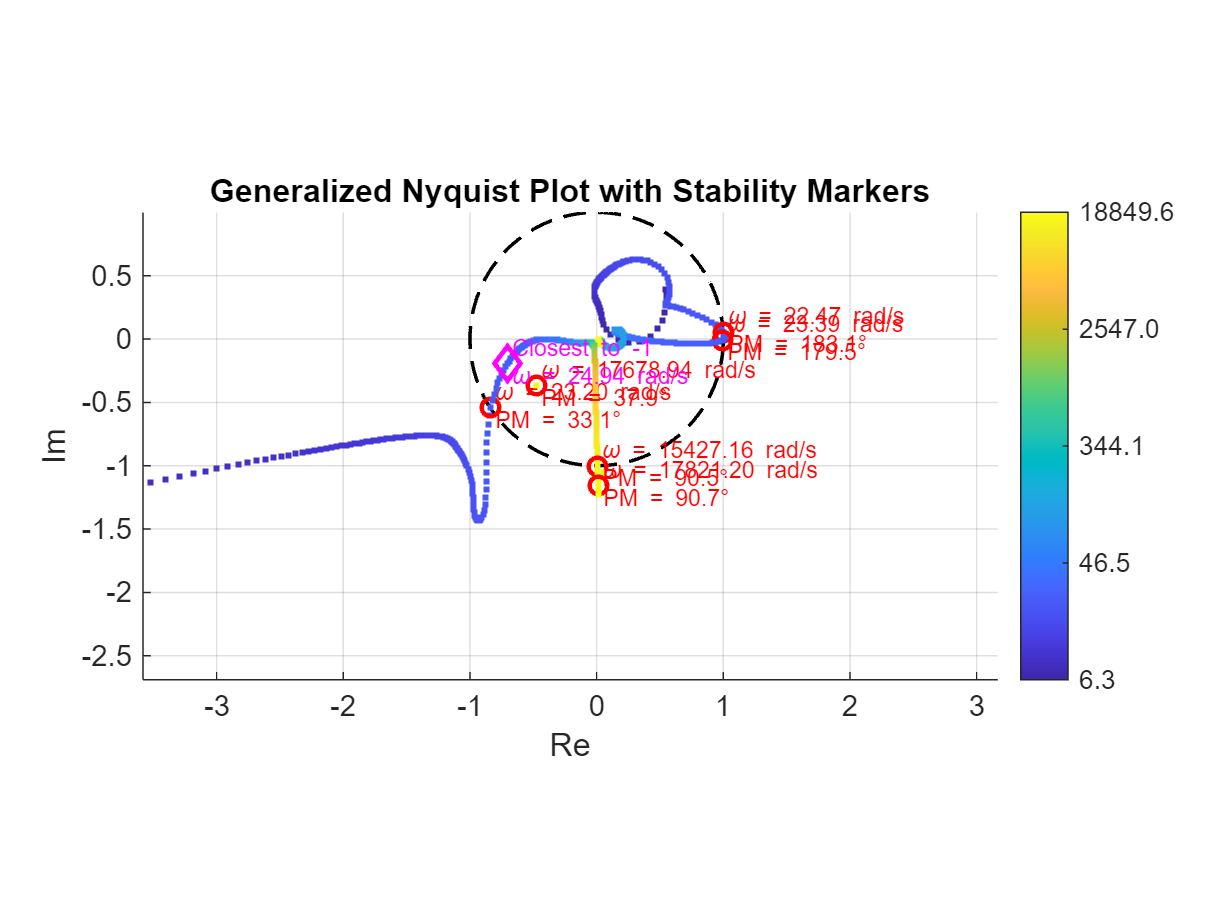

% Identify critical margins using Nyquist Plot
generalizedNyquistPlotwithCrossing(L1, wpos); 

eigL = encirclementNyquistPlot(L1,w); % Number of encirclement of the critical (-1,0) point

Encirclements by eigenvalue λ₁: -1
Encirclements by eigenvalue λ₂: 0


You can observe the generalized Nyquist plot and see that the eigen plots for eigen functions is closest to the critical point, -1+0j, at 4 H. This is the gain cross-over frequency at which the system is not adequately damped. 

**Interpretation of Each Crossing:**

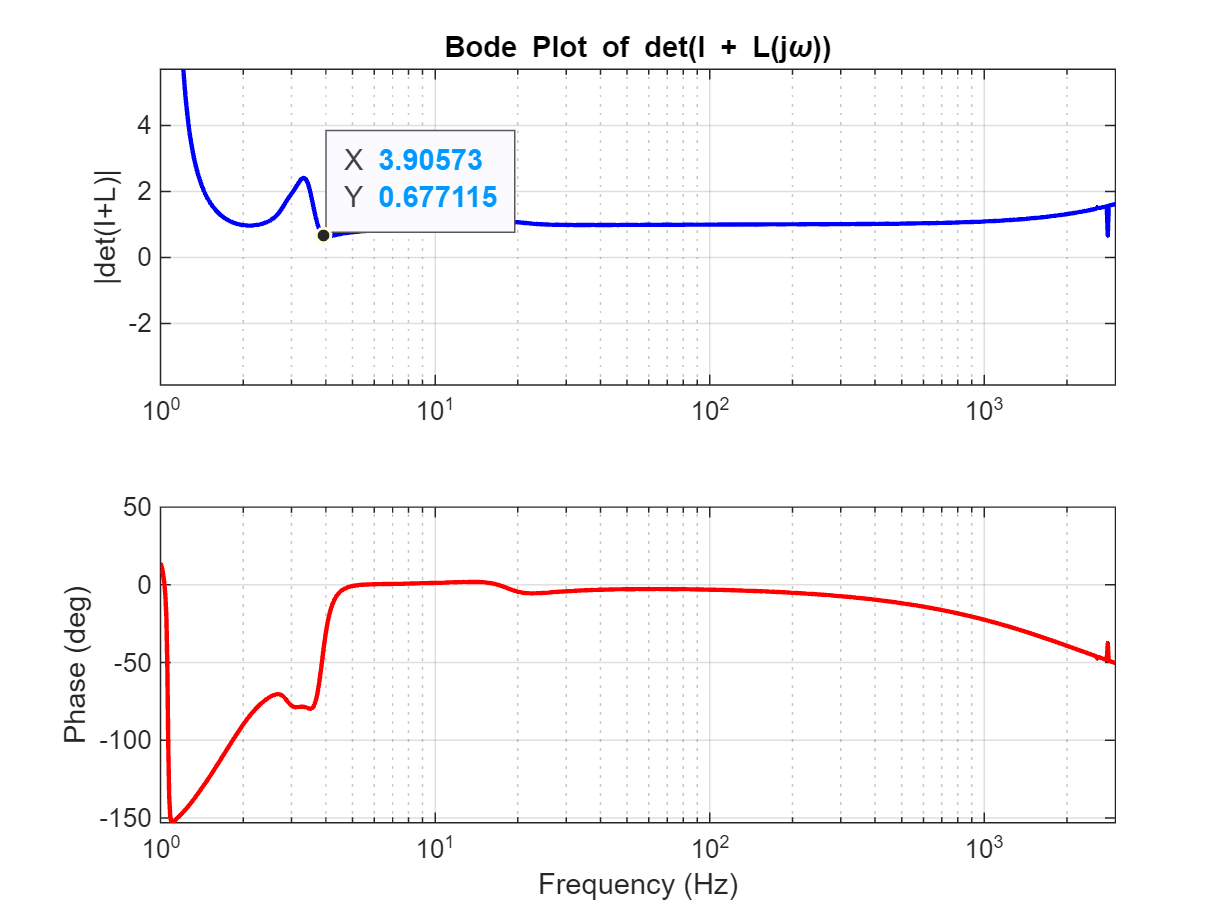

bodeDeterminant(eigL, w,scan); % Bode plot of det(I +L(jω))

You observe the **deep notch** in magnitude around ~ 4 Hz.

The frequencies where ∣det (I+L(jω))∣→0, i.e., the loop transfer function is close to making the determinant zero, which is dangerous for stability.

#### Bode Plots of Eigen values of **Loop Gain (**L(s))

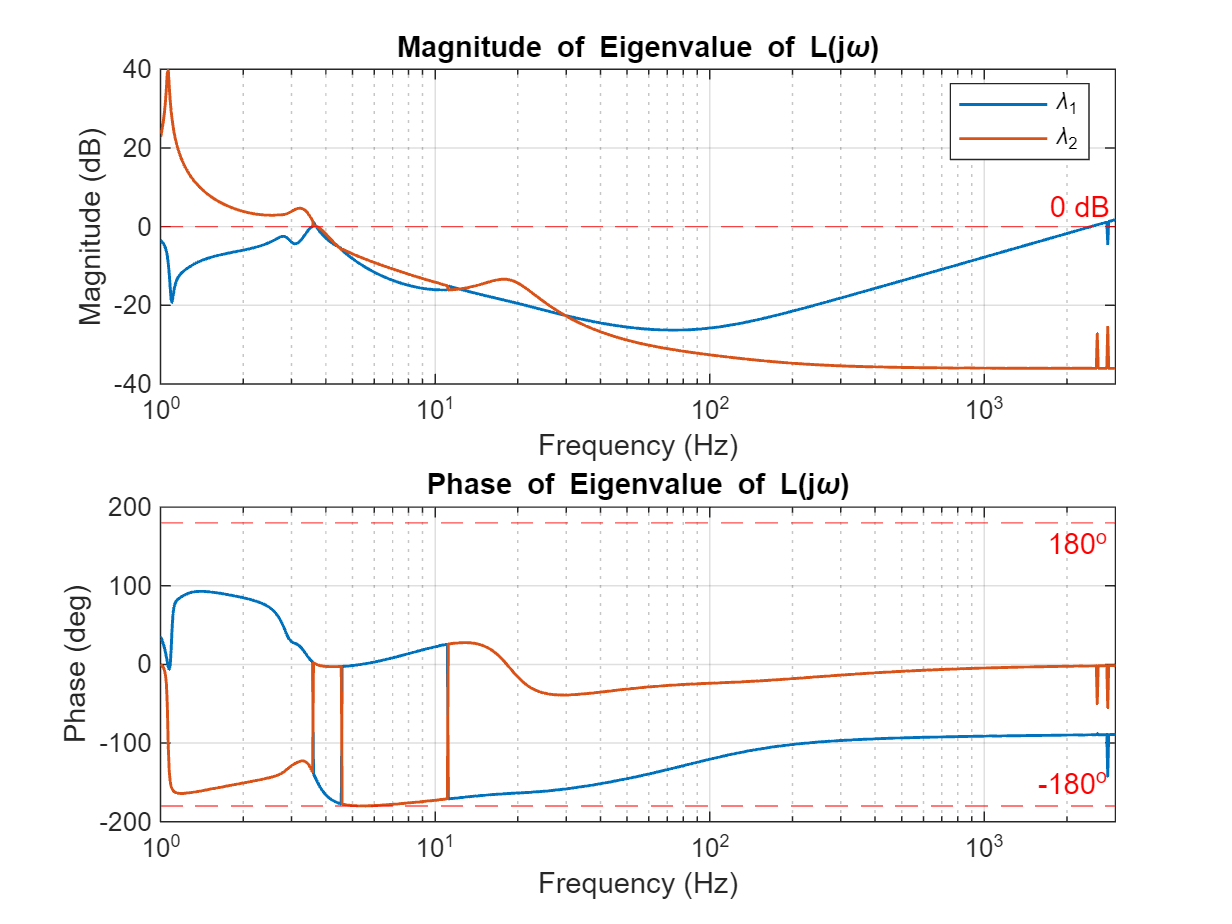

plotEigLBode(w,eigL,scan);

## Comparison with Time Domain Simulation

To validate the frequency-domain stability assessment obtained via generalized Nyquist analysis, a time-domain simulation was performed under a small disturbance scenario. Specifically, a 2 MW change in load was applied at t = 2 seconds, and the apparent power response of the VSC was analyzed.

scan.Vd = 0.0;  % Disturbance along D-axis (pu)
scan.Vq = 0.0;  % Disturbance along Q-axis (pu)
scan.Vdc = 0.0; % Disturbance along DC-axis (pu)
% Parameters of PRBS perturbation at offshore station during scanning onshore station
scan.Vd1 = 0.0; % Disturbance along D-axis (pu)
scan.Vq1 = 0.0; % Disturbance along Q-axis (pu)
scan.Vdc1 = 0.0;% Disturbance along DC-axis (pu)
% load switch
Tsim=4; % Time of simulation (s)
time.wind = Tsim + 1;
time.load = 3; % Time of load switch (s)
% Simulation Setup
simdata = sim(mdl);

**Collect Post Disturbance Measurements from POI at On-shore Station**

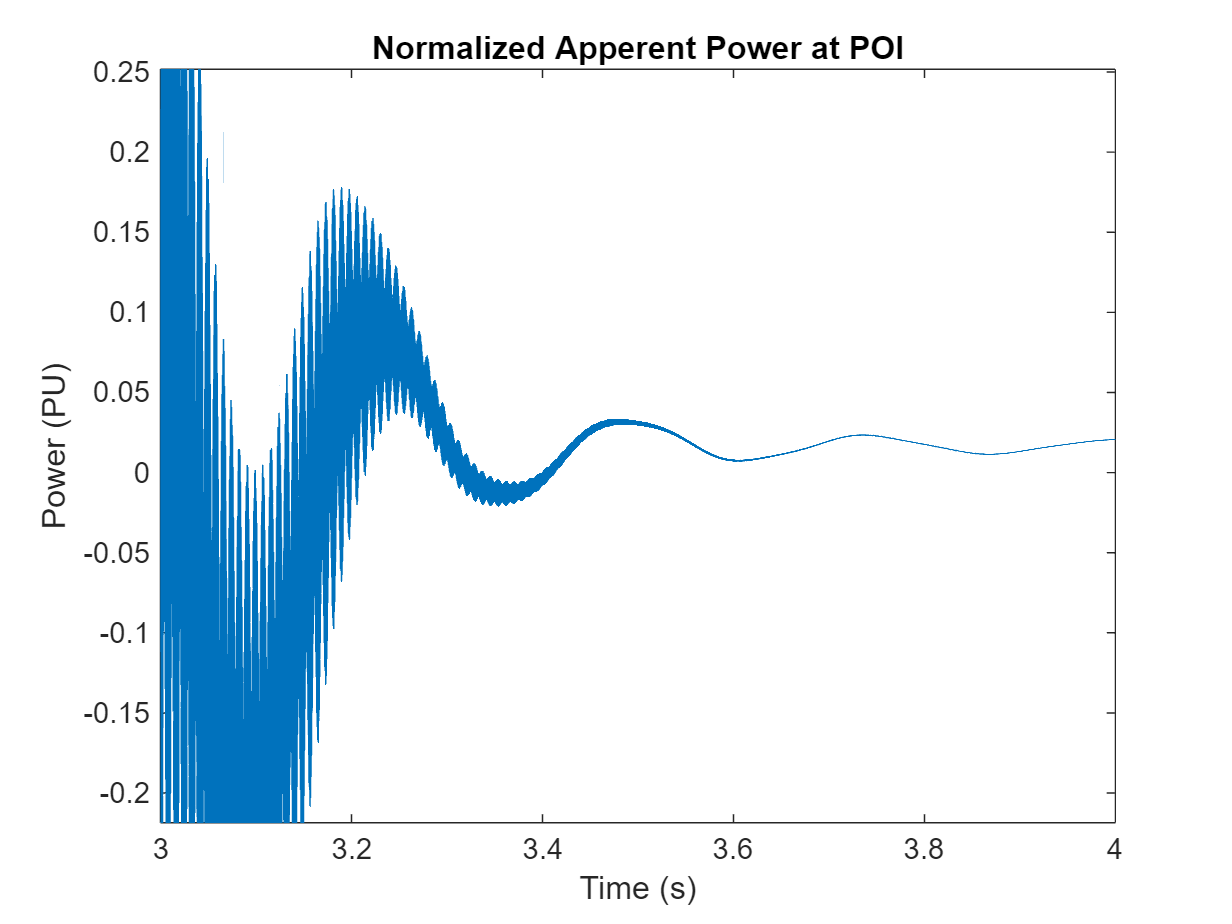

t = simdata.S.Time;           % Time vector
y = squeeze(simdata.S.Data);  % Apparent Power or other response variable

% Trim the signal to a window after the disturbance
idx = t >= time.load;
ttrim = t(idx);
ytrim = y(idx); 
ytrim = ytrim - mean(ytrim);
ytrim = ytrim / max(abs(ytrim));
figure;
plot(ttrim,ytrim); % Show Voltage at PCC
xlabel("Time (s)");
ylabel("Power (PU)");
title("Normalized Apperent Power at POI")
xlim([time.load time.load+1]);

**Plot FFT after Disturbance**

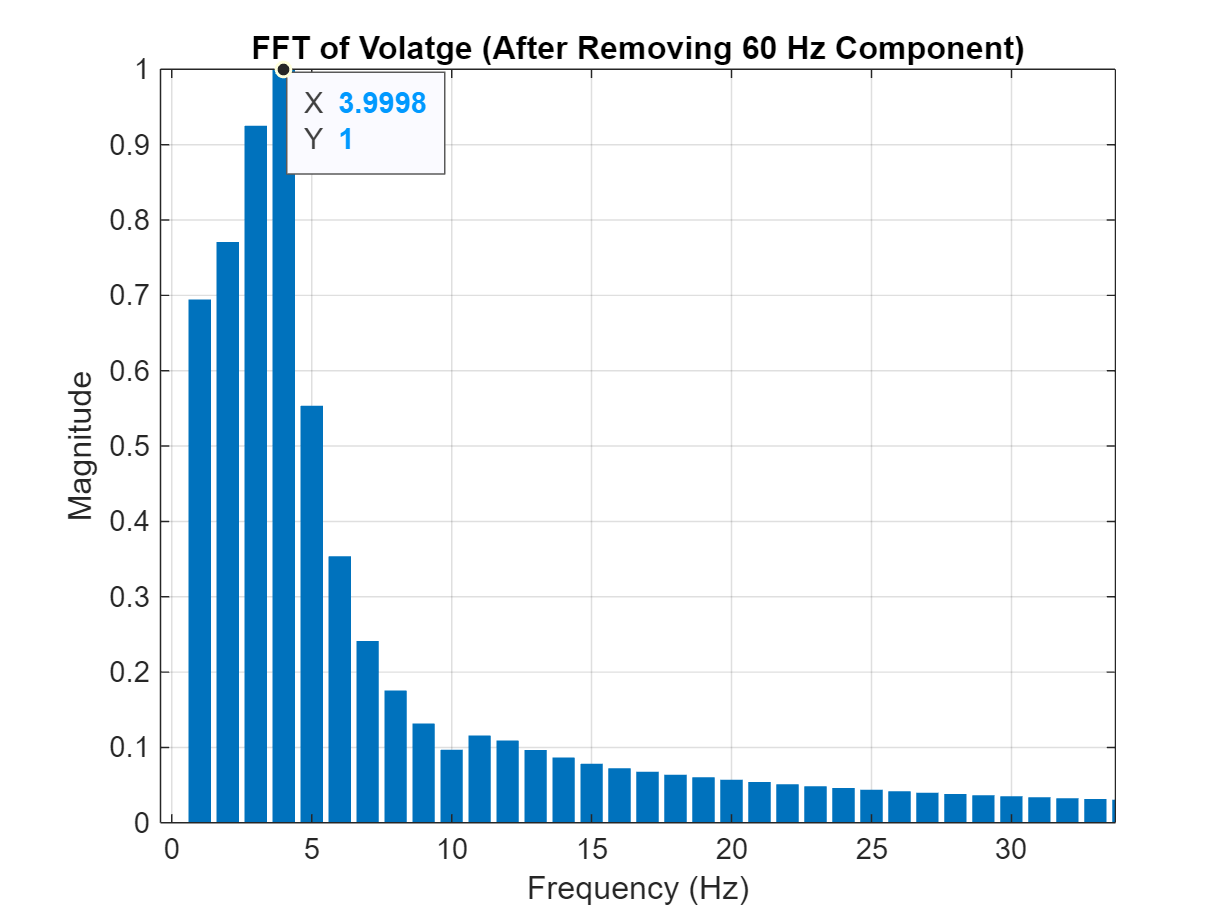

Fs = 1 / (t(2) - t(1));  % Sampling frequency
N = length(ytrim);       % Number of samples
Y = fft(ytrim);          % Compute FFT

% Frequency vector for full FFT
f_full = (0:N-1)*(Fs/N);       

% Find index closest to fundamental frequency (60 Hz)
[~, idx_60] = min(abs(f_full - 60));  

% Zero out 60 Hz and its symmetric component (for real signals)
Y(idx_60) = 0;
Y(N - idx_60 + 2) = 0;  % Mirror index for real-valued time signal

% Reconstruct signal without 60 Hz component
y_clean = real(ifft(Y));
Y_clean = abs(Y) / max(abs(Y));
figure;
bar(f_full(1:floor(N/2)), Y_clean(1:floor(N/2)));
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('FFT of Volatge (After Removing 60 Hz Component)');
xlim([0 4000]); grid on;

The post-disturbance signal was processed using the Fast Fourier Transform (FFT) to extract the dominant oscillatory components. The frequency with the highest amplitude in the FFT spectrum corresponds to the most energetic mode excited by the disturbance, in this case the dominant frequency from simulation is 3.99 Hz.

This value aligns closely with the critical point as predicted by the Nyquist eigenvalue and Bode plot analysis, i.e., at the 3.96 Hz, where the eigenvalue trajectory approaches the critical point `−1+j0.`

## Conclusion

The impedance analysis of the HVDC system based on the DC and AC impedance model is verified with the time-domain simulation  results. The impedance and admittance product is used to evaluate system stability. If the impact of the impedance/ admittance of the DC-side ports are ignored, stability assessment conclusions may have been incorrect.